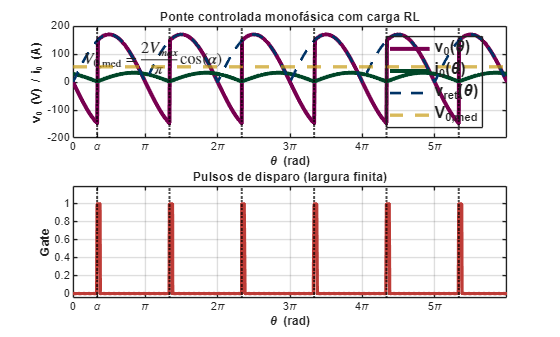

%% Retificador monofásico ONDA COMPLETA (ponte CONTROLADA) + carga RL

clear; clc; close all;

Vm      = 170;
f       = 60;
R       = 10;
L       = 50e-3;
alpha_d = 60;
ncy     = 12;
Ns      = 300000;
pw_d    = 8;
A_gate  = 1;

plotCycles = [6 8];

alpha = deg2rad(alpha_d);
pw    = deg2rad(pw_d);

theta = linspace(0, 2*pi*ncy, Ns);
dth   = theta(2) - theta(1);
omega = 2*pi*f;

v_s   = Vm*sin(theta);
v_ret = abs(v_s);

k  = floor((theta - alpha)/pi);
sg = (-1).^k;
v0 = sg .* v_s;

i0 = zeros(size(theta));
for n = 2:numel(theta)
    di_dt = (v0(n) - R*i0(n-1))/L;
    i0(n) = i0(n-1) + di_dt*(dth/omega);
end

Vmed = 2*Vm*cos(alpha)/pi;

Np = 2*ncy;
theta_fire = alpha + (0:(Np-1))*pi;

gate = zeros(size(theta));
for kk = 1:numel(theta_fire)
    gate = gate + A_gate * (theta >= theta_fire(kk) & theta <= (theta_fire(kk) + pw));
end

statale.maincolor = [0   51  102]/255;
statale.lilla     = [120 0   80 ]/255;
statale.darkgreen = [0   70  40 ]/255;
statale.red       = [190 60  55 ]/255;
statale.yellow    = [200 155 20 ]/255;

LW = 3.0;

T  = 1/f;
c1 = plotCycles(1);
c2 = plotCycles(2);

t1 = (c1-1)*T;
t2 = c2*T;
th1 = omega*t1;
th2 = omega*t2;

idx = (theta >= th1) & (theta <= th2);

thetaP = theta(idx);
v0P    = v0(idx);
i0P    = i0(idx);
vretP  = v_ret(idx);
gateP  = gate(idx);

thetaRel = thetaP - thetaP(1);

inWin = (theta_fire >= thetaP(1)) & (theta_fire <= thetaP(end));
theta_fire_rel = theta_fire(inWin) - thetaP(1);

figure('Color','w');

i0P(i0P<0) = 0;
ax1 = subplot(2,1,1);
plot(thetaRel, v0P,   'LineWidth', LW, 'Color', statale.lilla); hold on;
plot(thetaRel, i0P.*4,'LineWidth', LW, 'Color', statale.darkgreen);
plot(thetaRel, vretP, '--',        'LineWidth', 2,  'Color', statale.maincolor);
hmed = yline(Vmed, '--', 'LineWidth', 2.5);
hmed.Color = statale.yellow;
grid on;

title('Ponte controlada monofásica com carga RL');
ylabel('v_0 (V) / i_0 (A)');
xlabel('\theta (rad)');

txt = '$V_{0,\mathrm{med}}=\frac{2V_{max}}{\pi}\cos(\alpha)$';
text(0.02*thetaRel(end), 0.92*max(vretP+eps), txt, ...
    'Interpreter','latex', 'FontWeight','bold', 'FontSize', 12, ...
    'VerticalAlignment','top');

for kk = 1:numel(theta_fire_rel)
    xline(theta_fire_rel(kk), ':k', 'LineWidth', 1.5);
end

lgd = legend('v_0(\theta)','i_0(\theta)','v_{ret}(\theta)','V_{0,med}', 'Location','best');
lgd.FontSize   = 12;
lgd.FontWeight = 'bold';
lgd.Color      = 'none';

ax1.XLabel.FontWeight = 'bold';
ax1.YLabel.FontWeight = 'bold';

ax2 = subplot(2,1,2);
plot(thetaRel, gateP, 'LineWidth', 2.5, 'Color', statale.red); hold on;
grid on;
ylim([-0.05 1.2*A_gate]);
ylabel('Gate');
xlabel('\theta (rad)');
title('Pulsos de disparo (largura finita)');

for kk = 1:numel(theta_fire_rel)
    xline(theta_fire_rel(kk), ':k', 'LineWidth', 1.5);
end

ax2.XLabel.FontWeight = 'bold';
ax2.YLabel.FontWeight = 'bold';

linkaxes([ax1 ax2],'x');

k2 = floor(thetaRel(end)/pi);
xt = (0:k2)*pi;

if ~isempty(theta_fire_rel)
    xt = unique(sort([xt theta_fire_rel(1)]));
end

set([ax1 ax2], 'XLim', [0 thetaRel(end)], 'XTick', xt);

labs = strings(size(xt));
for kk = 1:numel(xt)
    if ~isempty(theta_fire_rel) && abs(xt(kk) - theta_fire_rel(1)) < 1e-12
        labs(kk) = "\alpha";
    else
        m = xt(kk)/pi;
        if abs(m - 0) < 1e-12
            labs(kk) = "0";
        elseif abs(m - 1) < 1e-12
            labs(kk) = "\pi";
        else
            labs(kk) = sprintf('%g\\pi', m);
        end
    end
end
set([ax1 ax2], 'XTickLabel', labs);